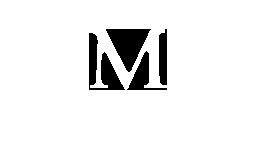

M = load('StudentData/FeaturesM');
T = load('StudentData/FeaturesT');

ObjectNumber = 1;
imshow(M.Data(ObjectNumber).Normal.Image)

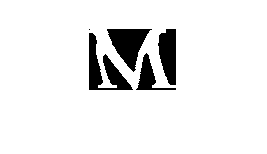


imshow(M.Data(ObjectNumber).W1.Image)

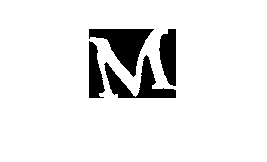

imshow(M.Data(ObjectNumber).W2.Image)

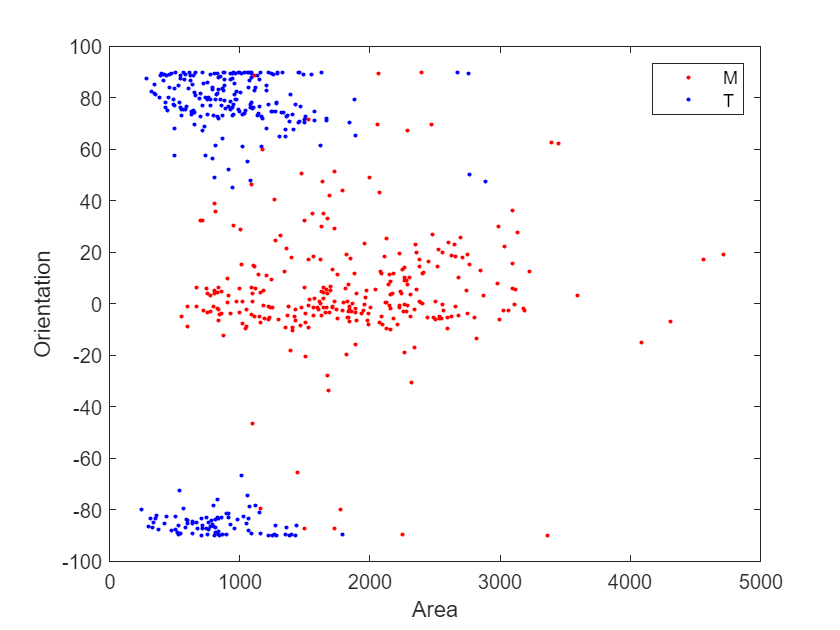


figure;
n=300;
X1=zeros(12,n);
for k = 1:n
plot(M.Data(k).Normal.Area,M.Data(k).Normal.Orientation,('.r')); hold on
plot(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,('.b')); hold on
X1(1,k)=M.Data(k).Normal.Area;
X1(2,k)=M.Data(k).Normal.Circularity;
X1(3,k)=M.Data(k).Normal.ConvexArea;
X1(4,k)=M.Data(k).Normal.Eccentricity;
X1(5,k)=M.Data(k).Normal.EquivDiameter;
X1(6,k)=M.Data(k).Normal.EulerNumber;
X1(7,k)=M.Data(k).Normal.Extent;
X1(8,k)=M.Data(k).Normal.MajorAxisLength;
X1(9,k)=M.Data(k).Normal.MinorAxisLength;
X1(10,k)=M.Data(k).Normal.Orientation;
X1(11,k)=M.Data(k).Normal.Perimeter;
X1(12,k)=M.Data(k).Normal.Solidity;
X1(1,k+n)=T.Data(k).Normal.Area;
X1(2,k+n)=T.Data(k).Normal.Circularity;
X1(3,k+n)=T.Data(k).Normal.ConvexArea;
X1(4,k+n)=T.Data(k).Normal.Eccentricity;
X1(5,k+n)=T.Data(k).Normal.EquivDiameter;
X1(6,k+n)=T.Data(k).Normal.EulerNumber;
X1(7,k+n)=T.Data(k).Normal.Extent;
X1(8,k+n)=T.Data(k).Normal.MajorAxisLength;
X1(9,k+n)=T.Data(k).Normal.MinorAxisLength;
X1(10,k+n)=T.Data(k).Normal.Orientation;
X1(11,k+n)=T.Data(k).Normal.Perimeter;
X1(12,k+n)=T.Data(k).Normal.Solidity;
end
xlabel('Area');
ylabel('Orientation');
legend('M','T');

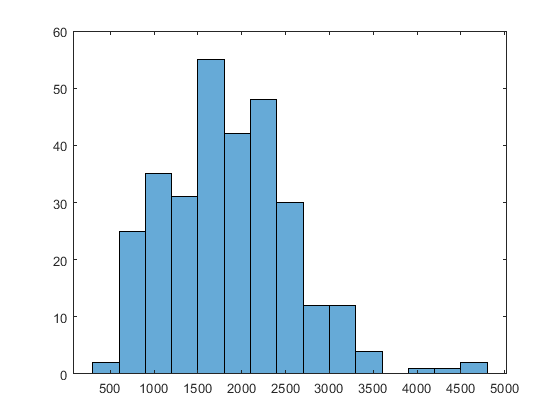

figure

histogram(X1(1,1:300));

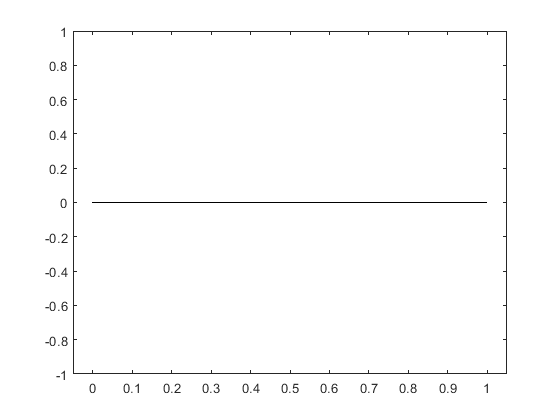

figure
histogram(X1(1,3001:600));

Task 2

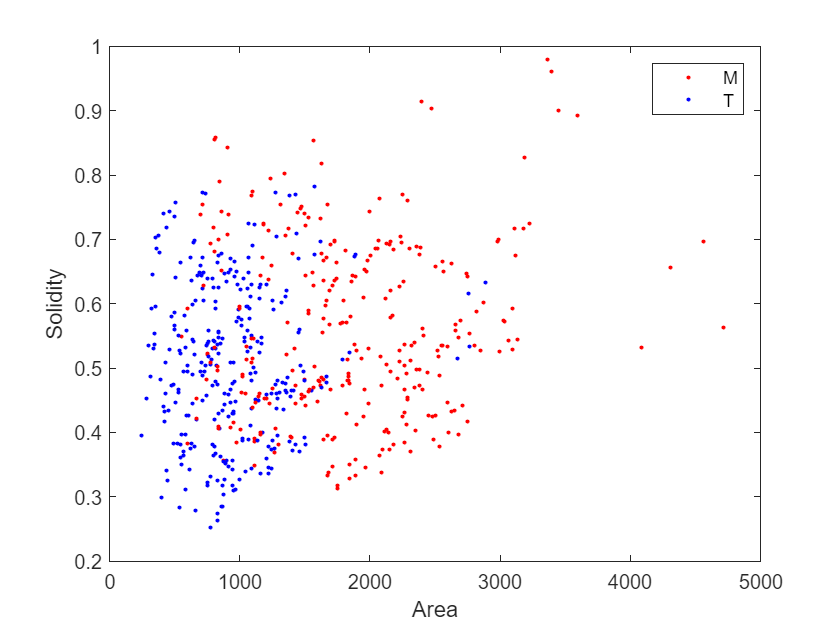

figure;
for k = 1:300
plot(M.Data(k).Normal.Area,M.Data(k).Normal.Solidity,('.r')); hold on
plot(T.Data(k).Normal.Area,T.Data(k).Normal.Solidity,('.b')); hold on
end
xlabel('Area');
ylabel('Solidity');
legend('M','T');

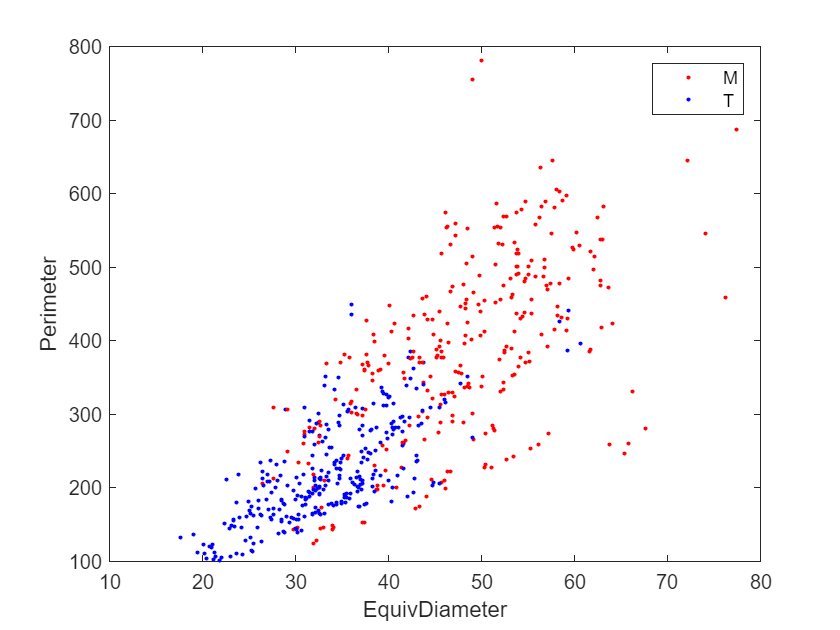

figure;
for k = 1:300
plot(M.Data(k).Normal.EquivDiameter,M.Data(k).Normal.Perimeter,('.r')); hold on
plot(T.Data(k).Normal.EquivDiameter,T.Data(k).Normal.Perimeter,('.b')); hold on
end
xlabel('EquivDiameter');
ylabel('Perimeter');
legend('M','T');

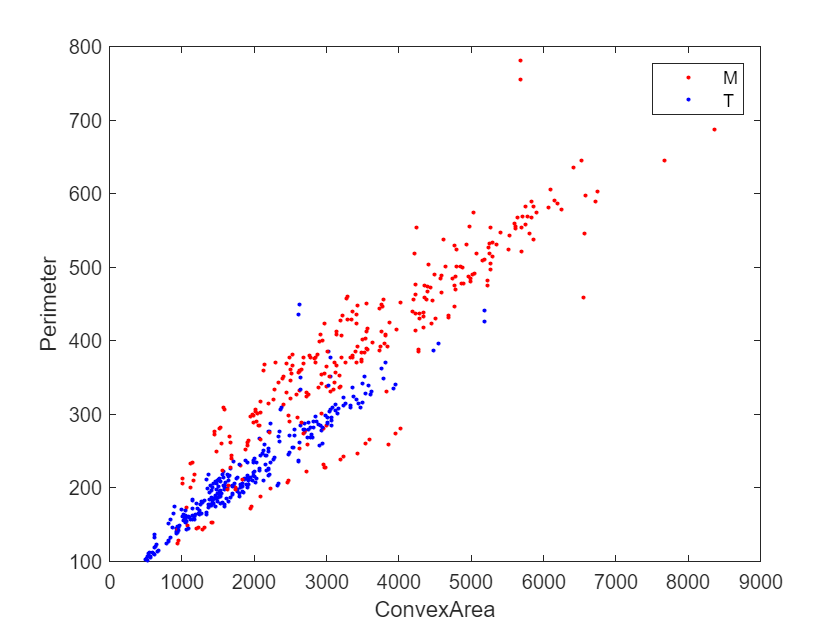

figure;
for k = 1:300
plot(M.Data(k).Normal.ConvexArea,M.Data(k).Normal.Perimeter,('.r')); hold on
plot(T.Data(k).Normal.ConvexArea,T.Data(k).Normal.Perimeter,('.b')); hold on
end
xlabel('ConvexArea');
ylabel('Perimeter');
legend('M','T');

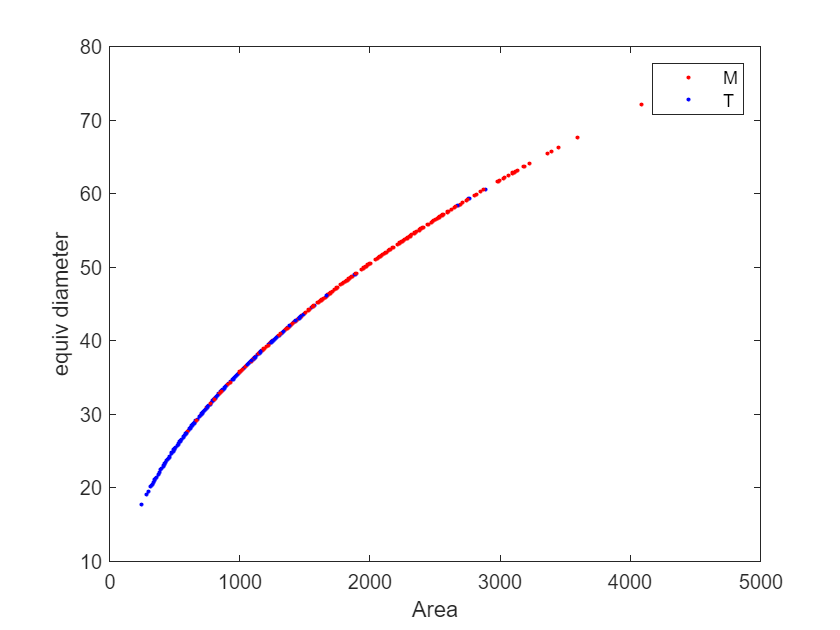

figure;
for k = 1:300
plot(M.Data(k).Normal.Area,M.Data(k).Normal.EquivDiameter,('.r')); hold on
plot(T.Data(k).Normal.Area,T.Data(k).Normal.EquivDiameter,('.b')); hold on
end
xlabel('Area');
ylabel('equiv diameter');
legend('M','T');

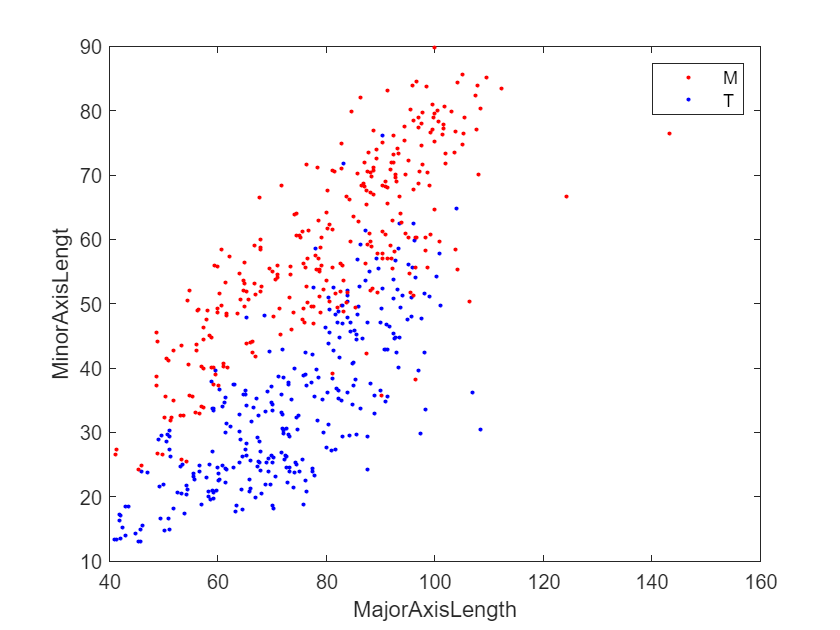

figure;
for k = 1:300
plot(M.Data(k).Normal.MajorAxisLength,M.Data(k).Normal.MinorAxisLength,('.r')); hold on
plot(T.Data(k).Normal.MajorAxisLength,T.Data(k).Normal.MinorAxisLength,('.b')); hold on
end
xlabel('MajorAxisLength');
ylabel('MinorAxisLengt');
legend('M','T');

ErrorsA = 0;
ErrorsD = 0;
for k = 1:300
if(ClassifierDT(M.Data(k).Normal) == 1) % Detected class "1", (our "T")
ErrorsA = ErrorsA + 1;
end
if(ClassifierDT(T.Data(k).Normal) == 0) % Detected class "0", (our "M")
ErrorsD = ErrorsD + 1;
end
end
disp(ErrorsA)

   127



disp(ErrorsD)

    49




ErrorsA = 0;
ErrorsD = 0;
for k = 301:600
if(ClassifierDT(M.Data(k).Normal) == 1) % Detected class "1", (our "T")
ErrorsA = ErrorsA + 1;
end
if(ClassifierDT(T.Data(k).Normal) == 0) % Detected class "0", (our "M")
ErrorsD = ErrorsD + 1;
end
end
disp(ErrorsA)

   125



disp(ErrorsD)

    46



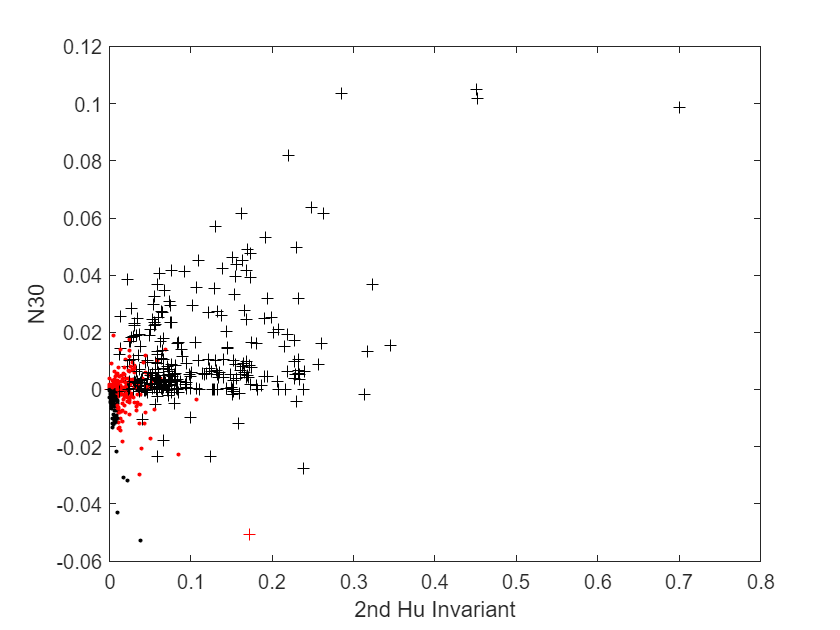

ErrorsA = 0;
ErrorsD = 0;
figure;
for k = 1:300
if(ClassifierDT2(M.Data(k).Normal) == 1) % Detected class "1", (our "T")
ErrorsA = ErrorsA + 1;
plot(M.Data(k).Normal.HuInvariants.I1,M.Data(k).Normal.Moments.N30,'.r'); hold on
else
plot(M.Data(k).Normal.HuInvariants.I1,M.Data(k).Normal.Moments.N30,'.k'); hold on
end
if(ClassifierDT2(T.Data(k).Normal) == 0) % Detected class "0", (our "M")
ErrorsD = ErrorsD + 1;
plot(T.Data(k).Normal.HuInvariants.I1,T.Data(k).Normal.Moments.N30,'+r'); hold on
else
plot(T.Data(k).Normal.HuInvariants.I1,T.Data(k).Normal.Moments.N30,'+k'); hold on
end
end
xlabel('2nd Hu Invariant');
ylabel('N30');

Task 3

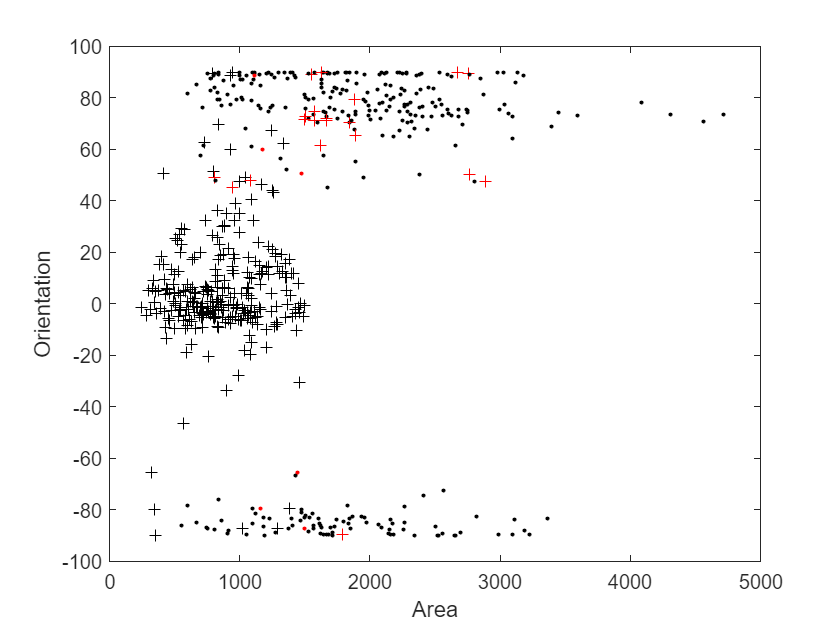

ErrorsM = 0;
ErrorsT = 0;
figure;
for k = 1:300
if(ClassifierDT4(M.Data(k).Normal) == 1) % Detected class "1", (our "T")
ErrorsM = ErrorsM + 1;
plot(M.Data(k).Normal.Area,M.Data(k).Normal.Orientation,'.r'); hold on
else
plot(M.Data(k).Normal.Area,T.Data(k).Normal.Orientation,'.k'); hold on
end
if(ClassifierDT4(T.Data(k).Normal) == 0) % Detected class "0", (our "M")
ErrorsT = ErrorsT + 1;
plot(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,'+r'); hold on
else
plot(T.Data(k).Normal.Area,M.Data(k).Normal.Orientation,'+k'); hold on
end
end
xlabel('Area');
ylabel('Orientation');

disp(ErrorsM)

     6



disp(ErrorsT)

    20



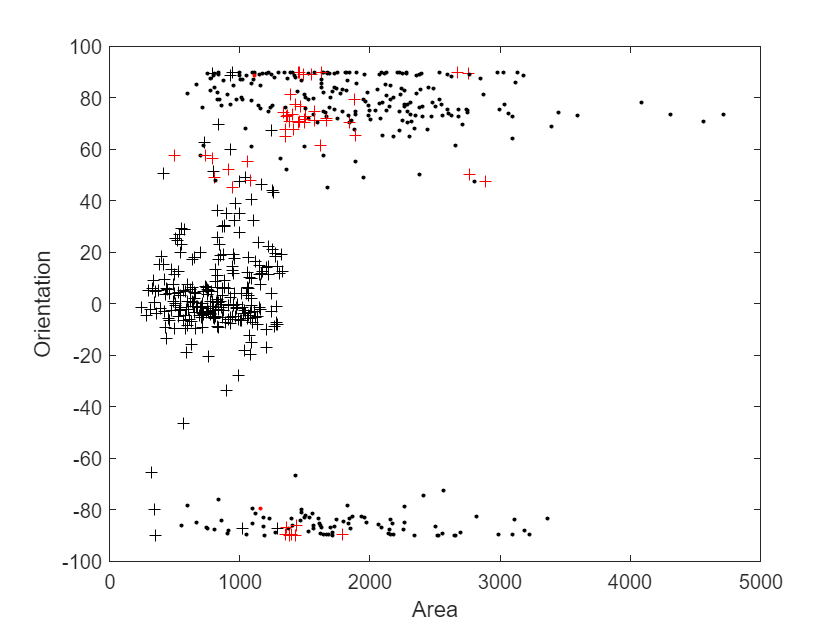

ErrorsM = 0;
ErrorsT = 0;
figure;
for k = 1:300
if(ClassifierDT3(M.Data(k).Normal) == 1) % Detected class "1", (our "T")
ErrorsM = ErrorsM + 1;
plot(M.Data(k).Normal.Area,M.Data(k).Normal.Orientation,'.r'); hold on
else
plot(M.Data(k).Normal.Area,T.Data(k).Normal.Orientation,'.k'); hold on
end
if(ClassifierDT3(T.Data(k).Normal) == 0) % Detected class "0", (our "M")
ErrorsT = ErrorsT + 1;
plot(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,'+r'); hold on
else
plot(T.Data(k).Normal.Area,M.Data(k).Normal.Orientation,'+k'); hold on
end
end
xlabel('Area');
ylabel('Orientation');

disp(ErrorsM)

     2



disp(ErrorsT)

    48



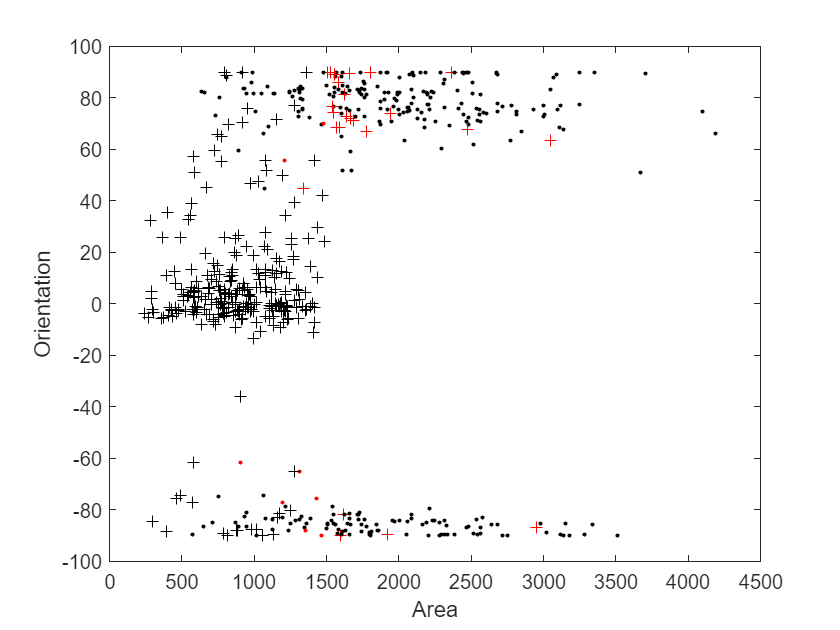

ErrorsM = 0;
ErrorsT = 0;
figure;
for k = 301:600
if(ClassifierDT4(M.Data(k).Normal) == 1) % Detected class "1", (our "T")
ErrorsM = ErrorsM + 1;
plot(M.Data(k).Normal.Area,M.Data(k).Normal.Orientation,'.r'); hold on
else
plot(M.Data(k).Normal.Area,T.Data(k).Normal.Orientation,'.k'); hold on
end
if(ClassifierDT4(T.Data(k).Normal) == 0) % Detected class "0", (our "M")
ErrorsT = ErrorsT + 1;
plot(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,'+r'); hold on
else
plot(T.Data(k).Normal.Area,M.Data(k).Normal.Orientation,'+k'); hold on
end
end
xlabel('Area');
ylabel('Orientation');

disp(ErrorsM)

     8



disp(ErrorsT)

    26



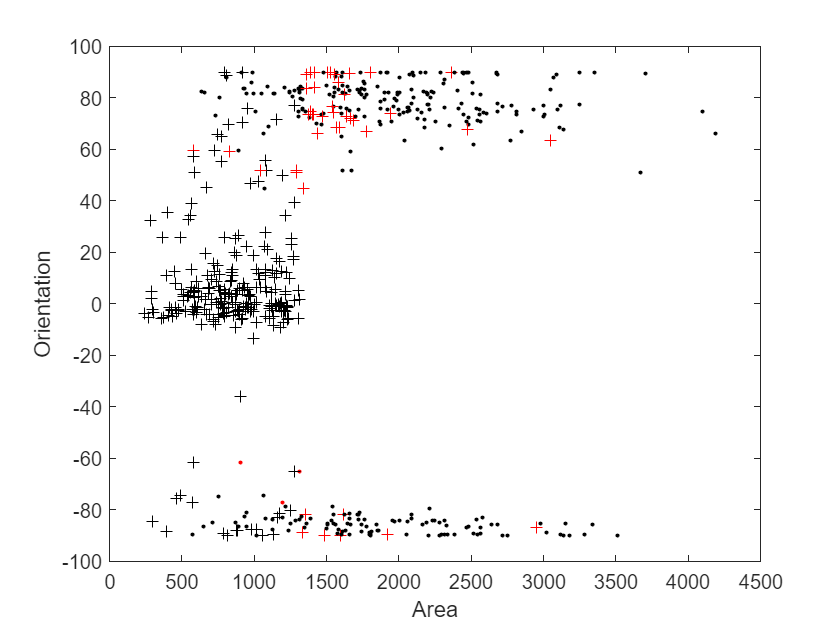

ErrorsM = 0;
ErrorsT = 0;
figure;
for k = 301:600
if(ClassifierDT3(M.Data(k).Normal) == 1) % Detected class "1", (our "T")
ErrorsM = ErrorsM + 1;
plot(M.Data(k).Normal.Area,M.Data(k).Normal.Orientation,'.r'); hold on
else
plot(M.Data(k).Normal.Area,T.Data(k).Normal.Orientation,'.k'); hold on
end
if(ClassifierDT3(T.Data(k).Normal) == 0) % Detected class "0", (our "M")
ErrorsT = ErrorsT + 1;
plot(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,'+r'); hold on
else
plot(T.Data(k).Normal.Area,M.Data(k).Normal.Orientation,'+k'); hold on
end
end
xlabel('Area');
ylabel('Orientation');

disp(ErrorsM)

     3



disp(ErrorsT)

    48



I select features: Area, Orientation

function [Class] = ClassifierDT4(Object)
    weight=0;
    if(Object.Area > 1500)
        weight=weight-1;%M
    else
        weight=weight+1;%T
    end
    if(Object.Orientation > 50)
        weight=weight+1;%T
    elseif(Object.Orientation < -60)
        weight=weight+1;%T
    else
        weight=weight-1;%M
    end
    if weight>0
        Class=1;%T
    else
        Class=0;%M
    end
end

function [Class] = ClassifierDT3(Object)
    weight=0;
    if(Object.Area > 1330)
        weight=weight-1;%M
    else
        weight=weight+1;%T
    end
    if(Object.Orientation >60)
        weight=weight+1;%T
    elseif(Object.Orientation < -60)
        weight=weight+1;%T
    else
        weight=weight-1;%M
    end
    if weight>0
        Class=1;%T
    else
        Class=0;%M
    end
end

function [Class] = ClassifierDT2(Object)
    if(Object.Moments.N30 > 0)
        Class = 1;
    elseif(Object.Moments.N30 < -0.03)
        Class = 0;
    elseif(Object.HuInvariants.I1 < 0.01)
        Class = 0;
    else
        Class = 1;
    end
end

function [Class] = ClassifierDT(Object)

    if(Object.Moments.N30 > 0)
        Class = 1;
    else
        Class = 0;
    end
end